clear;

% u_t + u u_x = 0
% u(x,0) = x
% soln -> x/(t+1), for t>=0

u = @(x, t) x ./ (t+1);

N = 100;
xx = linspace(0, 4, N);
tt = linspace(0, 4, N);

PlotPDE(u, xx, tt, 5);

xMin = -5; xMax = 5;
tMin = 0; tMax = 1;
N = 500; nx = 11; nt = 6;
xx = linspace(xMin, xMax, N);
x0 = linspace(xMin, xMax, nx);
t0 = linspace(tMin, tMax, nt);

u = @(x, t) x ./ (t+1);

f = figure();
xlabel('x'); ylabel('t'); zlabel('u(x,t0)');
xticks(-5:1:5); yticks(0:0.2:1); zticks(-5:1:5);
axis([xMin xMax tMin tMax -5 5]);

hold on;
% function u(x,t0) for fixed t0
for i = 1:nt
    t = repelem(t0(i), N);
    plot3(xx, t, u(xx,t), 'k-', 'LineWidth', 1.5);
end
% characteristic curves for fixed x0
for i = 1:nx
    t = (xx-x0(i)) / (u(x0(i),0)+eps);
    plot3(xx, t, u(xx,t), 'k:', 'LineWidth', 1);
end
% saving figures
view(20, 35);
exportgraphics(f, [pwd, '/Figures/intro_f1_3d.png']);
view(0, 90);
exportgraphics(f, [pwd, '/Figures/intro_f1_char.png']);
hold off;

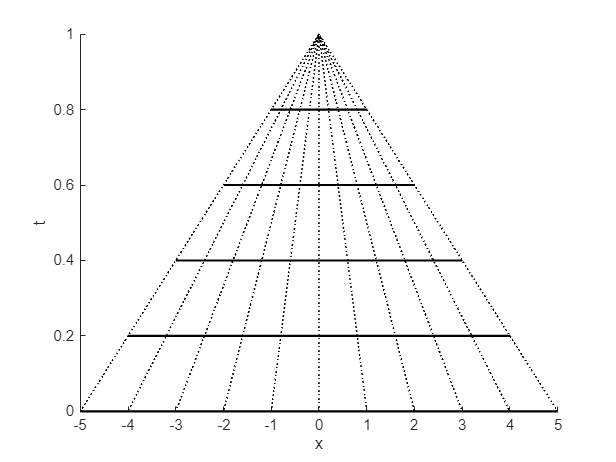

v = @(x, t) x ./ (t-1);

g = figure();
view(20, 35);
xlabel('x'); ylabel('t'); zlabel('u(x,t0)');
xticks(-5:1:5); yticks(0:0.2:1); zticks(-5:1:5);
axis([xMin xMax tMin tMax -5 5]);

hold on;
% function v(x,t0) for fixed t0
for i = 1:nt
    t = repelem(t0(i)+eps, N);
    plot3(xx, t, v(xx,t), 'k-', 'LineWidth', 1.5);
end
% characteristic curves for fixed x0
for i = 1:nx
    t = (xx-x0(i)) / (v(x0(i),0)+eps);
    plot3(xx, t, v(xx,t)+eps, 'k:', 'LineWidth', 1);
end
% saving figures
% view(20, 35);
% exportgraphics(g, [pwd, '/Figures/intro_f2_3d.png']);
view(0, 90);
exportgraphics(g, [pwd, '/Figures/intro_f2_char.png']);
hold off;

% u_t + u u_x = 0
% u(x,0) = x
% soln -> x/(t-1), for 0 <= t <1

u = @(x, t) x ./ (t-1);

N = 100;
xx = linspace(0, 4, N);
tt = linspace(0, 1, N);

PlotPDE(u, xx, tt, 5);

% u_t + u u_x = 0

syms u(x,t)
u(x,t) = piecewise(x <= t, 1, ...
                   (t<x)&(x<1), (1-x)/(1-t), ...
                   x >= 1, 0);

N = 100;
xx = linspace(0, 1, N);
tt = linspace(0, 1, N);

PlotPDE(u, xx, tt, 5);